# 基于RST灵敏度函数塑形的管道ANC（Carmona & Alvarado, 2000）

闭环系统的性能受到干扰（包括输入端和输出端干扰）的很大影响。因此完全地分析它们的影响非常重要。因此，灵敏度函数在鲁棒控制理论中无论是对于干扰影响分析还是对于闭环系统的鲁棒性分析都非常重要。

在ANC问题中，通常考虑两种类型的干扰：输出干扰$e\left(t\right)$和测量噪声$b\left(t\right)$。

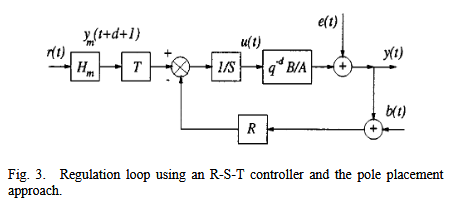

尽管文中使用了“鲁棒控制”的语言，但实际上并没有使用**H∞合成**，**μ-synthesis**或者**loop shaping**等现代鲁棒控制方法，而是回到**RST多项式法（极点配置+灵敏度整形）**。通过灵敏度模板和预指定因子，控制器设计考虑了频率不确定性，使用鲁棒控制思想指导RST控制器的设计。

**（1）工程可实现性**：H∞ 和 μ-synthesis 虽然在理论上成熟了，但在实时嵌入式 ANC 上应用少（算力/实现难度）。设计出来的结果往往还是要转化为IIR滤波器才能落地，而不见得比RST更直接。对于需要实时实现的控制器，20~30阶已经很高。

**（2）鲁棒性的“软化”**：控制器设计仍然保留了鲁棒的思想，把鲁棒性能的约束转换为灵敏度函数的频率模板（在±10%的带宽衰减满足3dB的降幅），把鲁棒设计的思想"嵌"进了极点配置的预先指定多项式中。

## 1 鲁棒控制设计基础

### RST控制器设计（Diophantine方程求解）

论文把RST设计归结为求解多项式等式：$P_DP_F=AH_SS_1+q^{-d}BH_RR_1$

其中$P_DP_F$是预先指定的多项式（designer chooses），前者包含需要放入闭环的主导极点，后者是用来控制输入灵敏度/限制控制器高频激励的实极点。$H_R, H_S
$为预设控制器零极点，可以把特定的零点和陷波直接放进去。

### 稳定性裕度

`在鲁棒控制器的设计中，模态裕度 `$\Delta M$` 和延迟裕度 `$\Delta \tau \;$` 是基本的裕度。第一个定义了以[-1, j0] 为中心的圆的半径，并与开环传递函数 `$G_{\textrm{OL}} \left(z\right)$` 的奈奎斯特图相切。我们有 `


$$\Delta M = |1 + G_{OL}(e^{-i\omega T_s})|_{\min} = |S_{ye}^{-1}(e^{-i\omega T_s})|_{\min}= (|S_{ye}(e^{-i\omega T_s})|_{\max})^{-1} = (||S_{ye}||_{\infty})^{-1}.$$


`因此，`$|S_{\textrm{ye}} |$ `在某些频率的减少将意味着`$\Delta M$`的增加。因此，`$\Delta M$`用于定义输出灵敏度函数`$S_{\textrm{ye}}$模`的上界。此外，由于非线性系统的稳定性的圆盘准则，`$\Delta M$`给出了闭环系统中允许的非线性和时变参数元素的特性的界限。 `

`在传播现象的情况下，强烈建议考虑时延不确定性。因此，延迟裕度`$\Delta \tau \;$`成为鲁棒控制设计的基础。时间延迟裕度是从相位裕度`$\Delta \phi \;\;$`导出的，定义为`$\Delta \tau = \frac{\Delta \phi}{\omega_{cr}},$`其中 `$\omega_{cr}
$` 是剪切频率，即奈奎斯特图与单位圆相交的频率。工程惯用`$\Delta M \approx -6 \text{dB}$` 和 `$\Delta \tau \approx T_s$`。`

`[29]中说明，时延裕度迫使 `$S_{\textrm{ye}} \left(z^{-1} \right)$` 的模数保持在由上/下模板定义的区域内。表达式 `$W\left(z\right)$` 与 `$H_{\infty }$` 方法中使用的加权函数有关。举例而言，在具有一个采样周期延迟时间裕度的通常情况下，模板为： `

$|W^{-1}(z^{-1})|_{\text{low}} = 1 - |1 - z^{-1}|^{-1}
$`和 `$|W^{-1}(z^{-1})|_{\text{up}} = 1 + |1 - z^{-1}|^{-1}.
$

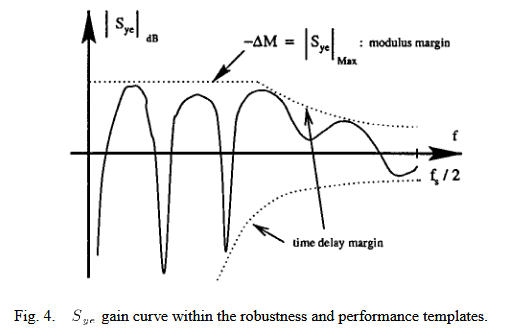

`在鲁棒控制框架中，如上所述，对`$\Delta M$`和`$\Delta \tau \;$`的约束表达了鲁棒稳定性目标。同样，我们已经看到标称性能目标包括拒绝属于不同类型问题遇到的扰动源频谱的频率。尽管问题种类不同，但对非理想性能的尊重使得输出灵敏度函数设计中出现一些拒绝峰值，如图4所示。在不详细说明（参见[24]和[29]）的情况下，拒绝特定频率是通过在压制多项式 `$S_S(q^{-1})$`上施加零来获得的。在该频率的某些不确定性裕度的情况下，可以使用一对具有适当阻尼比的复共轭零点。为了方便地将`$S_{\textrm{ye}}$`曲线拟合到不同的模板中，可以使用压制多项式`$R_S(q^{-1})$`的零点在频率轴上施加一些截断。`

### Remark1 灵敏度函数

`输出灵敏度函数/主灵敏度函数 `$S=S_{\textrm{ye}} \;$，`互补灵敏度函数`$T=-S_{\textrm{yb}}$`。这里，为了避免与多项式 RST 混淆，我们将在本文中使用表达式下面的表达式。`


$$S_{ye} = \frac{AS}{P} \quad S_{ue} = -\frac{AR}{P} \quad S_{yb} = -q^{-d}\frac{BR}{P}.$$


### Remark2 互补灵敏度函数

`在鲁棒控制理论中，经常使用互补灵敏度函数`$T = -S_{yb}$`来研究对建模不确定性的鲁棒性（参见文献[30]）。但在此我们采用了`$S_{\textrm{ye}} \;$`，因为通过单一曲线即可展示频率抑制性能和所需的鲁棒性度裕。这在我们的应用中更为便捷。`

### Remark3 输入灵敏度函数

## 2 标称性能问题

## 3 鲁棒性能问题

## 4 系统模型

文章将控制器设计方法应用于工程实践：由加热器/空调产生的噪声通过管道传播。为了不使初始问题复杂化，不要直接将加热器于管道连接（避免与平均流相关的复杂流体力学问题），而是专注于风扇噪声通过开口管道传播的问题。

% 零极点分析脚本 - 函数封装版本（修复版）
% 分析给定传递函数的零点和极点特性，输出阻尼系数ξ和频率Fs
addpath('functions');
clear; close all; clc;

%% 定义多项式系数
d = 6;
% 分母多项式系数 (极点)
A_coeffs = [1 -1.3941 -0.0389 +1.2131 -1.1895 +0.0430 +1.0517 -0.6267];

% 分子多项式系数 (零点) 
B_coeffs = [0.0304 +0.0709 -0.0947 -0.0170 -0.0104 -0.0787 +0.0414 +0.0380 ...
            +0.0250 +0.0366 -0.0584 +0.0540 -0.0862 -0.6267];

% 采样频率 (假设，可根据实际情况修改)
Fs = 2000; % Hz
Ts = 1/Fs;

% 定义频率点（单位 Hz）
f_nom = [100, 200];    % 名义频率
w_nom = 2*pi*f_nom*Ts; % 数字角频率

% 分析零点和极点
[poles, zers, pole_data, zero_data] = analyze_zeros_poles(A_coeffs, B_coeffs, Fs);

% 打印结果表格
print_analysis_table(poles, zers, pole_data, zero_data, Fs);

系统阶数: 7 (分母)
零点个数: 13
极点个数: 7

==================== 极点分析 ====================
零/极点                 频率(Hz)          阻尼系数ξ           类型                  
----------------------------------------------------------------------
-0.893+0.288i        900.5544        0.0224          复数(稳定)              
-0.893-0.288i        900.5544        0.0224          复数(稳定)              
0.266+0.915i         409.9039        0.0371          复数(稳定)              
0.266-0.915i         409.9039        0.0371          复数(稳定)              
0.871+0.325i         113.5834        0.1991          复数(稳定)              
0.871-0.325i         113.5834        0.1991          复数(稳定)              
0.9049               0.0000          ∞ (过阻尼)         实数(稳定)              

==================== 零点分析 ====================
零/极点                 频率(Hz)          阻尼系数ξ           类型                  
----------------------------------------------------------------------
-3.2273              0.0000          -∞ (不稳定)        实数(不稳定)      

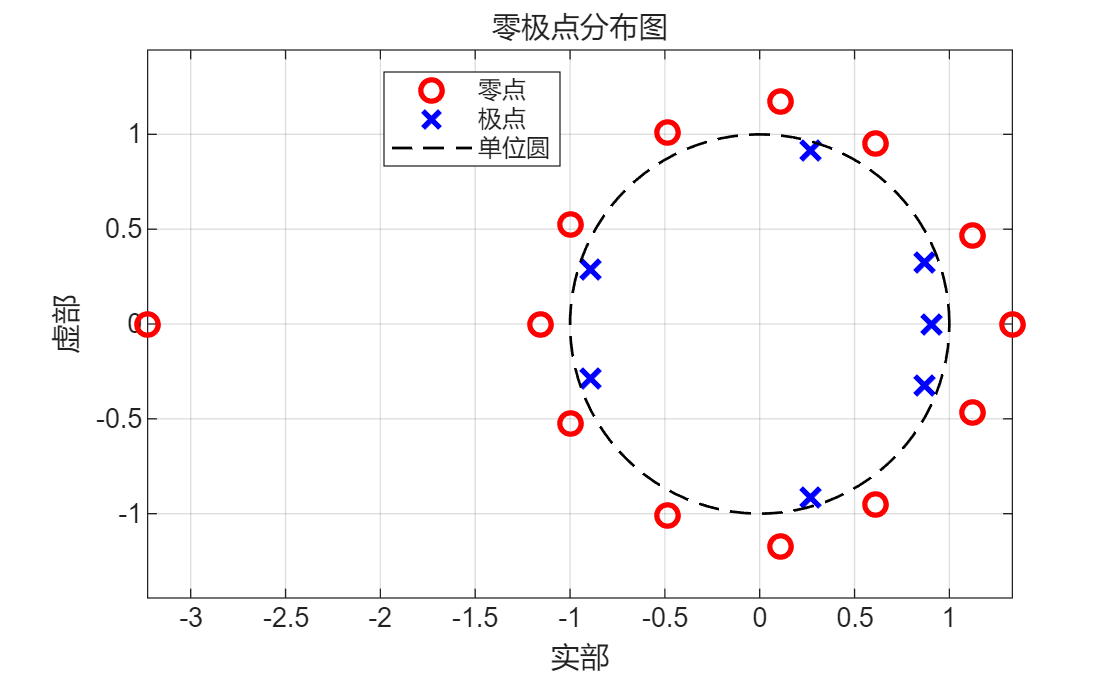

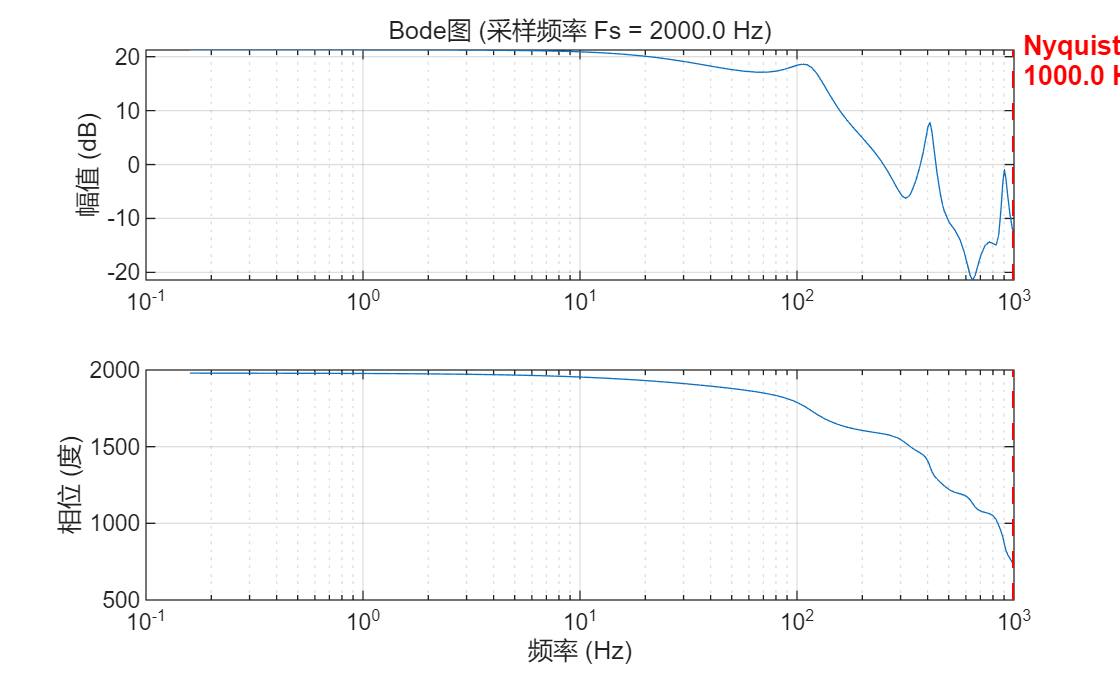

% 绘制图形
plot_system_analysis(B_coeffs, A_coeffs, Ts, poles, zers);

## 5 控制器设计

### 总体设计流程

**（1）辨识**：得到$A, B$以及系统若干的自然模态；

**（2）选取主导极点**：把需要的自然模态放入$P_D$以保留/控制这些极点；

**（3）选取辅助极点**：取若干个实极点（可取重根，如$(1-\alpha q^{-1})^n$），以控制输入灵敏度/限制高频能量。

**（4）指定预先设计部分：**

**（5）求解Diophantine方程**

A = A_coeffs(:).';
B_star = B_coeffs(:).';
B = [zeros(1,d), B_star];
% --- helper: build discrete 2nd-order factor for frequency f(Hz) and damping zeta ---
make_2nd = @(f, zeta) ...
    ( @(Ts) ...
        ( ...
            ( 1 - 2*exp(-zeta*2*pi*f*Ts)*cos(2*pi*f*Ts*sqrt(1-zeta^2)) * [0 1] + exp(-2*zeta*2*pi*f*Ts) * [0 0 1] ) ...
        ) ...
    );
% Helper: discrete second-order factor (function handle)
so = @(f,zeta) second_order_factor(f,zeta,Ts);

### K1设计：标称性能+鲁棒稳定性

针对固定的噪声频率（100Hz与200Hz），在R多项式中设置零点，使灵敏度函数在这两个频率出现深凹；补充辅助极点（filtering poles）来增强鲁棒性，得到20阶控制器（含7各自然模态+频率拒绝项）。在 **窄带噪声控制（100 Hz, 200 Hz 等）** 时效果最好（50–60 dB 衰减）。

根据(7),(8)，选取多重根$P_F(q^{-1})=(1-0.46q^{-1})^9$作为辅助极点（保证控制器高频部分衰减块，减轻执行器的负担）；7个自然模态$P_D(q^{-1})$作为主导极点以提高系统的鲁棒性（如果不不把被控对象的自然极点纳入闭环，系统鲁棒性将会交叉，容易激发不期望的共振）。

% ---------------- K1 (Nominal performance + robust stability) ----------------
% P_F = (1 - 0.46 q^-1)^9
PF1 = 1;
for i = 1:9, PF1 = conv(PF1, [1 -0.46]); end
PD1 = A; % <<< REPLACE with product of identified-mode factors if available
P_desired = conv(PD1, PF1);

% S_S: rejects 100 and 200 Hz with null damp (zero damping -> r=1)
SS1 = conv( so(100, 0.0), so(200, 0.0) ); % two quadratic zero-factors
% plus two damped complex poles at 600 Hz with zeta=0.015 (paper says these are used)
SS1 = conv(SS1, so(600, 0.015));
% paper notes degree of preassigned part SS is already six (approx)
RS1 = 1;

% Solve Diophantine -> get S1,R1
[R1,S1,nrp,nsp] = bezoutd(A,B,SS1,RS1,P_desired);
checkBezout(A,B,S1,R1,SS1,RS1,P_desired);

  验证结果: 相对误差 = 2.8748524271e-15
  Bezout方程解验证成功!


% Build loop open-loop L = G * (T/R) and sensitivity Sye = 1/(1+L)
R_K1 = conv(R1, RS1);
S_K1 = conv(S1, SS1);
G = tf(B, A, Ts);
K1_eq = tf(R_K1, S_K1, Ts);
L1 = G * K1_eq;
Sye1 = 1 / (1 + L1);

### K2设计：鲁棒性能+鲁棒稳定性

考虑频率的不确定性（100Hz与200Hz，附近±10%），把原来精确零点换成成对的共轭零点并加入阻尼形成频带拒绝；控制器仍选择为20阶，在200Hz和200Hz仍可实现17dB,19dB的衰减，且在频率漂移±10%时仍有效。在 **频率有小范围不确定性** 时仍能保持 15–20 dB 的衰减。

% ---------------- K2 (Robust performance + robust stability) ----------------
% P_F same as K1
PF2 = PF1;
PD2 = A; % placeholder as above: PD includes seven natural modes in paper
P_desired = conv(PF2, PD2);

% S_S now uses banded (damped) zeros at 100,200,600 with specified zeta
SS2 = conv( so(100, 0.04), so(200, 0.02) );
SS2 = conv(SS2, so(600, 0.015));
RS2 = 1;

% Solve Diophantine -> get S1,R1
[R2,S2,nrp,nsp] = bezoutd(A,B,SS2,RS2,P_desired);
checkBezout(A,B,S2,R2,SS2,RS2,P_desired);

  验证结果: 相对误差 = 2.8503769186e-15
  Bezout方程解验证成功!



% Build loop open-loop L = G * (T/R) and sensitivity Sye = 1/(1+L)
R_K2 = conv(R2, RS2);
S_K2 = conv(S2, SS2);
K2_eq = tf(R_K2, S_K2, Ts);
L2 = G * K2_eq;
Sye2 = 1 / (1 + L2);

### K3设计：宽带噪声

当我们想覆盖30~170Hz的宽带拒绝时，可在R中放置多个共轭零点和阻尼，对多个频率形成陷波；但控制器需要30阶以上，实现复杂。尽管部分频率有13dB衰减，但在150~170Hz区间出现噪声放大。宽带问题更适合前馈自适应方法，鲁棒反馈难以处理。

% ---------------- K3 (Broad-band attempt, many preassigned zeros) ----------
% P_F = (1 - 0.48 q^-1)^17
PF3 = 1;
for i = 1:17, PF3 = conv(PF3, [1 -0.48]); end
PD3 = A; % placeholder
P_desired = conv(PD3,PF3);

% S_S includes six target factors per paper (50,100,150,200,250,318 Hz with given zeta)
SS3 = so(50, 0.1);
SS3 = conv(SS3, so(100, 0.1));
SS3 = conv(SS3, so(150, 0.1));
SS3 = conv(SS3, so(200, 0.1));
SS3 = conv(SS3, so(250, 0.07));
SS3 = conv(SS3, so(318, 0.06));
% R_S includes two factors at high freq 540, 730 Hz (zeta=0)
RS3 = conv( so(540, 0.0), so(730, 0.0) );

% Solve Diophantine -> get S3,R3
[R3,S3,nrp,nsp] = bezoutd(A,B,SS3,RS3,P_desired);
checkBezout(A,B,S3,R3,SS3,RS3,P_desired);

  验证结果: 相对误差 = 1.0752954218e-14
  Bezout方程解验证成功!



% Build loop open-loop L = G * (T/R) and sensitivity Sye = 1/(1+L)
R_K3 = conv(R3, RS3);
S_K3 = conv(S3, SS3);
K3_eq = tf(R_K3, S_K3, Ts);
L3 = G * K3_eq;
Sye3 = 1 / (1 + L3);

## 6 控制器频响

控制器稳定性分析

灵敏度函数频响函数分析

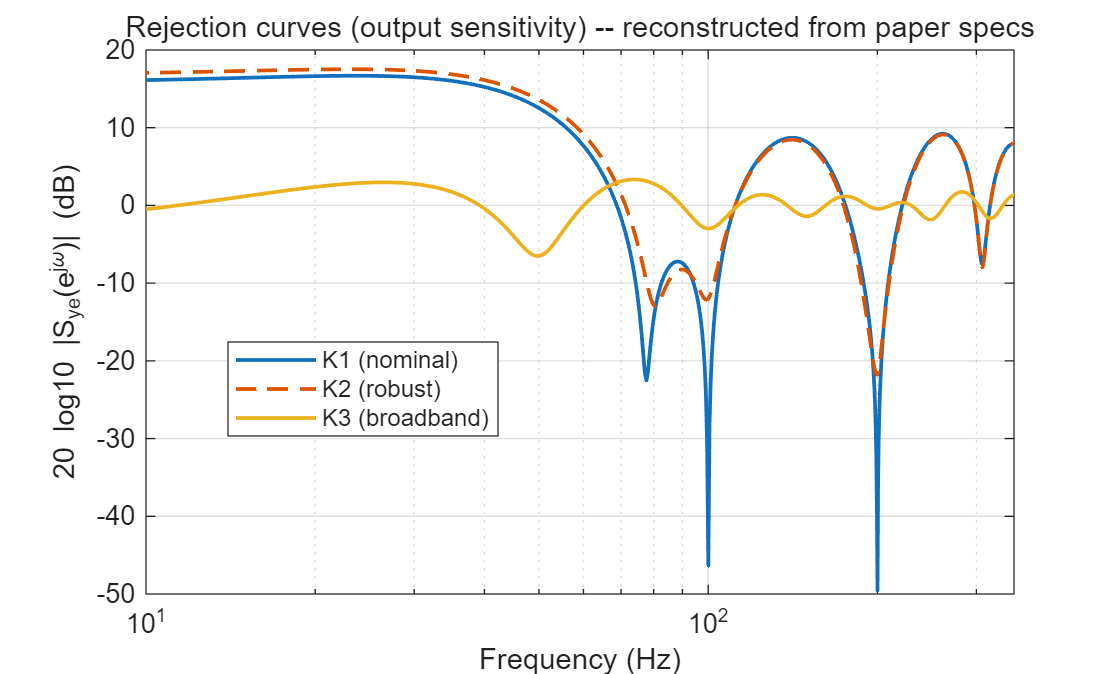

%% --- Plot Sye curves (rejection curves) ---
fplot = linspace(5, 1000, 2000); % Hz
w = 2*pi*fplot; % rad/s

[mag1, ~] = bode(Sye1, w); mag1 = squeeze(mag1);
[mag2, ~] = bode(Sye2, w); mag2 = squeeze(mag2);
[mag3, ~] = bode(Sye3, w); mag3 = squeeze(mag3);

figure;
semilogx(fplot, 20*log10(mag1), 'LineWidth', 1.4); hold on;
semilogx(fplot, 20*log10(mag2), '--','LineWidth', 1.4);
semilogx(fplot, 20*log10(mag3), 'LineWidth', 1.4);
xlabel('Frequency (Hz)');
ylabel('20 log10 |S_{ye}(e^{j\omega})| (dB)');
legend('K1 (nominal)','K2 (robust)','K3 (broadband)','location','best');
title('Rejection curves (output sensitivity) -- reconstructed from paper specs');
grid on; xlim([10 350]);

## 附录

%% 函数定义部分
function [poles, zeros, pole_data, zero_data] = analyze_zeros_poles(A_coeffs, B_coeffs, Fs)
    % 分析零点和极点的函数
    % 输入: A_coeffs - 分母系数, B_coeffs - 分子系数, Fs - 采样频率
    % 输出: poles, zeros - 根的值, pole_data, zero_data - 分析数据
    
    % 计算零点和极点
    poles = roots(A_coeffs);
    zeros = roots(B_coeffs);
    
    % 分析每个极点 - 使用结构体数组避免类型混合
    pole_data = struct('root', {}, 'freq_hz', {}, 'damping', {}, 'type', {});
    for i = 1:length(poles)
        [freq_hz, damping, type_str] = analyze_single_root(poles(i), Fs);
        pole_data(i).root = poles(i);
        pole_data(i).freq_hz = freq_hz;
        pole_data(i).damping = damping;
        pole_data(i).type = type_str;
    end
    
    % 分析每个零点
    zero_data = struct('root', {}, 'freq_hz', {}, 'damping', {}, 'type', {});
    for i = 1:length(zeros)
        [freq_hz, damping, type_str] = analyze_single_root(zeros(i), Fs);
        zero_data(i).root = zeros(i);
        zero_data(i).freq_hz = freq_hz;
        zero_data(i).damping = damping;
        zero_data(i).type = type_str;
    end
end

function [freq_hz, xi, type_str] = analyze_single_root(root_val, Fs)
    % 分析单个根的特性
    % 输入: root_val - 根值, Fs - 采样频率
    % 输出: freq_hz - 频率(Hz), xi - 阻尼系数, type_str - 类型字符串
    
    if isreal(root_val)
        % 实数根
        if abs(root_val) < 1e-10
            freq_hz = 0;
            xi = Inf; % 积分环节
            type_str = '积分环节';
        elseif abs(root_val) >= 1
            % 在单位圆外，不稳定
            freq_hz = 0; % 实数根没有振荡频率
            xi = -Inf; % 不稳定
            type_str = '实数(不稳定)';
        else
            % 在单位圆内，稳定
            freq_hz = 0; % 实数根没有振荡频率
            xi = Inf; % 过阻尼
            type_str = '实数(稳定)';
        end
    else
        % 复数根
        magnitude = abs(root_val);
        angle_val = angle(root_val);
        
        % 计算自然频率 (Hz)
        % 对于离散系统: wn_digital = angle, wn_continuous = angle * Fs / (2*pi)
        freq_hz = abs(angle_val) * Fs / (2*pi);
        
        % 计算阻尼系数 ξ
        % 对于离散系统: s = ln(z)/T, 其中T = 1/Fs
        % ξ = -real(s) / abs(s)
        if magnitude > 1e-10 % 避免除零错误
            s_equiv = log(root_val) * Fs; % 等效连续域极点
            
            if abs(s_equiv) > 1e-10
                xi = -real(s_equiv) / abs(s_equiv);
            else
                xi = 0;
            end
        else
            xi = 0;
        end
        
        % 稳定性判断
        if magnitude < (1 - 1e-10)
            type_str = '复数(稳定)';
        elseif abs(magnitude - 1) < 1e-10
            type_str = '复数(临界稳定)';
        else
            type_str = '复数(不稳定)';
            xi = -abs(xi); % 不稳定时阻尼系数为负
        end
        
        % 修正边界情况
        if xi > 1
            xi = min(xi, 1); % 限制阻尼系数范围
        end
    end
end

function print_analysis_table(poles, zeros, pole_data, zero_data, Fs)
    % 打印分析结果表格
    
    fprintf('系统阶数: %d (分母)\n', length(poles));
    fprintf('零点个数: %d\n', length(zeros));
    fprintf('极点个数: %d\n\n', length(poles));
    
    % 打印极点表格
    fprintf('==================== 极点分析 ====================\n');
    fprintf('%-20s %-15s %-15s %-20s\n', '零/极点', '频率(Hz)', '阻尼系数ξ', '类型');
    fprintf('%s\n', repmat('-', 1, 70));
    
    for i = 1:length(pole_data)
        root_val = pole_data(i).root;
        freq_hz = pole_data(i).freq_hz;
        xi = pole_data(i).damping;
        type_str = pole_data(i).type;
        
        if isreal(root_val)
            root_str = sprintf('%.4f', root_val);
        else
            root_str = sprintf('%.3f%+.3fi', real(root_val), imag(root_val));
        end
        
        if isinf(xi)
            if xi > 0
                xi_str = '∞ (过阻尼)';
            else
                xi_str = '-∞ (不稳定)';
            end
        else
            xi_str = sprintf('%.4f', xi);
        end
        
        fprintf('%-20s %-15.4f %-15s %-20s\n', root_str, freq_hz, xi_str, type_str);
    end
    
    fprintf('\n');
    
    % 打印零点表格
    fprintf('==================== 零点分析 ====================\n');
    fprintf('%-20s %-15s %-15s %-20s\n', '零/极点', '频率(Hz)', '阻尼系数ξ', '类型');
    fprintf('%s\n', repmat('-', 1, 70));
    
    for i = 1:length(zero_data)
        root_val = zero_data(i).root;
        freq_hz = zero_data(i).freq_hz;
        xi = zero_data(i).damping;
        type_str = zero_data(i).type;
        
        if isreal(root_val)
            root_str = sprintf('%.4f', root_val);
        else
            root_str = sprintf('%.3f%+.3fi', real(root_val), imag(root_val));
        end
        
        if isinf(xi)
            if xi > 0
                xi_str = '∞ (过阻尼)';
            else
                xi_str = '-∞ (不稳定)';
            end
        else
            xi_str = sprintf('%.4f', xi);
        end
        
        fprintf('%-20s %-15.4f %-15s %-20s\n', root_str, freq_hz, xi_str, type_str);
    end
    
    fprintf('\n注释:\n');
    fprintf('- ξ = 0: 无阻尼振荡\n');
    fprintf('- 0 < ξ < 1: 欠阻尼\n');
    fprintf('- ξ = 1: 临界阻尼\n');
    fprintf('- ξ > 1: 过阻尼\n');
    fprintf('- ξ < 0: 不稳定\n');
    fprintf('- 频率为0表示非振荡模式\n');
end

function plot_system_analysis(B_coeffs, A_coeffs, Ts, poles, zeros)
    % 绘制系统分析图形
    Fs = 1/Ts;
    sys = tf(B_coeffs, A_coeffs, Ts); % 离散系统，采样时间为1
    
    % 零极点图
    figure;
    if ~isempty(zeros)
        plot(real(zeros), imag(zeros), 'ro', 'MarkerSize', 8, 'LineWidth', 2); % 零点
        hold on;
    else
        hold on;
    end
    
    if ~isempty(poles)
        plot(real(poles), imag(poles), 'bx', 'MarkerSize', 10, 'LineWidth', 2); % 极点
    end
    
    % 添加单位圆
    theta = linspace(0, 2*pi, 100);
    plot(cos(theta), sin(theta), 'k--', 'LineWidth', 1);
    
    grid on;
    axis equal;
    xlabel('实部');
    ylabel('虚部');
    title('零极点分布图');
    
    if ~isempty(zeros) && ~isempty(poles)
        legend('零点', '极点', '单位圆', 'Location', 'best');
    elseif ~isempty(zeros)
        legend('零点', '单位圆', 'Location', 'best');
    elseif ~isempty(poles)
        legend('极点', '单位圆', 'Location', 'best');
    else
        legend('单位圆', 'Location', 'best');
    end
    
    % Bode图
    figure;
    try
        sys_discrete = tf(B_coeffs, A_coeffs, Ts);
        
        % 绘制Bode图
        [mag, phase, wout] = bode(sys_discrete);
        
        % 手动绘制Bode图以便添加标记
        subplot(2,1,1);
        semilogx(wout/(2*pi), 20*log10(squeeze(mag))); % 转换为Hz并绘制幅频图
        grid on;
        ylabel('幅值 (dB)');
        title(sprintf('Bode图 (采样频率 Fs = %.1f Hz)', Fs));
        
        % 添加奈奎斯特频率线到幅频图
        hold on;
        nyquist_freq = Fs/2;
        ylim_current = ylim;
        plot([nyquist_freq nyquist_freq], ylim_current, 'r--', 'LineWidth', 1.5);
        text(nyquist_freq*1.1, ylim_current(2)*0.9, sprintf('Nyquist\n%.1f Hz', nyquist_freq), ...
             'Color', 'red', 'FontSize', 10, 'FontWeight', 'bold');
        hold off;
        
        % 绘制相频图
        subplot(2,1,2);
        semilogx(wout/(2*pi), squeeze(phase)); % 转换为Hz并绘制相频图
        grid on;
        ylabel('相位 (度)');
        xlabel('频率 (Hz)');
        
        % 添加奈奎斯特频率线到相频图
        hold on;
        ylim_current = ylim;
        plot([nyquist_freq nyquist_freq], ylim_current, 'r--', 'LineWidth', 1.5);
        hold off;
        
    catch ME
        fprintf('绘制Bode图时出错: %s\n', ME.message);
        text(0.5, 0.5, '系统可能不稳定或无法绘制Bode图', 'HorizontalAlignment', 'center');
        title('Bode图 (系统可能不稳定)');
        axis([0 1 0 1]);
    end
end

%% ---------- 辅助函数：离散二阶因子（返回 q^-1 多项式系数 [1, c1, c2]) ----------
function fac = second_order_factor(f_hz, zeta, Ts)
    if f_hz == 0
        fac = 1; return;
    end
    wn = 2*pi*f_hz;
    r = exp(-zeta*wn*Ts);
    wd = wn*sqrt(max(0,1-zeta^2));
    c1 = -2*r*cos(wd*Ts);
    c2 = r^2;
    fac = [1, c1, c2];
end

%% ---------- 辅助函数：构造 conv 矩阵，但强制返回 targetRows x n 矩阵 ----------
% p: 多项式向量（行向量）， n: 想要"未知项"个数（列数）， targetRows: 期望的行数
function C = convmat_for_len(p, n, targetRows)
    p = p(:).'; % ensure row
    if n <= 0
        % no unknowns -> return an empty matrix with targetRows rows
        C = zeros(targetRows, 0);
        return;
    end
    m = length(p);
    L = m + n - 1; % natural number of rows for convmat
    % build matrix of size L x n first
    Ctemp = zeros(L, n);
    for j = 1:n
        Ctemp(j:(j+m-1), j) = p;
    end
    % if we need to enforce targetRows, pad or truncate accordingly
    if L < targetRows
        % pad with zero rows at bottom
        C = [Ctemp; zeros(targetRows - L, n)];
    elseif L > targetRows
        % truncate extra bottom rows (this should be rare - indicates inconsistent degree choices)
        C = Ctemp(1:targetRows, :);
    else
        C = Ctemp;
    end
end

%% ---------- 主函数：解 Diophantine 方程（稳健版） ----------
% PD, PF, A, B, SS, RS: 多项式系数（行向量），d: 整数延迟
% 返回 S = SS * S1, R = RS * R1, 以及 S1,R1 多项式系数（行向量）
function [S, R, S1, R1] = solve_diophantine(PD, PF, A, B, SS, RS, d)
    % ensure row vectors
    PD = PD(:).'; PF = PF(:).'; A = A(:).'; B = B(:).'; SS = SS(:).'; RS = RS(:).';
    % Left side
    Left = conv(PD, PF);
    Lleft = length(Left); % desired number of rows / coefficients
    % precomputed convs
    A_SS = conv(A, SS);
    B_RS = conv(B, RS);
    % compute unknown lengths (number of coefficients) per formula
    nS1 = max(0, Lleft - length(A_SS) + 1);
    nR1 = max(0, Lleft - d - length(B_RS) + 1);
    % build convolution matrices with enforced row counts
    C_AS = convmat_for_len(A_SS, nS1, Lleft);      % Lleft x nS1 (or Lleft x 0)
    C_BR_small = convmat_for_len(B_RS, nR1, Lleft - d); % (Lleft-d) x nR1 or empty
    % now shift C_BR by d rows (prepend zeros)
    if d > 0
        if isempty(C_BR_small)
            C_BR = zeros(Lleft, 0);
        else
            C_BR = [zeros(d, size(C_BR_small,2)); C_BR_small];
            % pad if needed
            if size(C_BR,1) < Lleft
                C_BR(end+1:Lleft, :) = 0;
            elseif size(C_BR,1) > Lleft
                C_BR = C_BR(1:Lleft, :);
            end
        end
    else
        % no shift needed
        if isempty(C_BR_small)
            C_BR = zeros(Lleft, 0);
        else
            C_BR = C_BR_small;
        end
    end
    % Now ensure both have Lleft rows
    if size(C_AS,1) < Lleft
        C_AS(end+1:Lleft, :) = 0;
    end
    if size(C_BR,1) < Lleft
        C_BR(end+1:Lleft, :) = 0;
    end

    % Compose full linear system: C_AS * s1 + C_BR * r1 = Left' 
    M = [C_AS, C_BR]; b = Left(:);
    % handle special case: no unknowns at all
    if isempty(M)
        % candidate solution: S1 = 1, R1 = 1
        S1 = 1; R1 = 1;
        S = conv(SS, S1);
        R = conv(RS, R1);
        % verify residual
        AS = conv(A, S);
        BR = conv(B, R)';
        resid = addPolynomials(Left(:), -addPolynomials(AS(:), [zeros(d,1); BR(1:end-d)])); %#ok<NASGU>
        % Can't use the inline conv in vectorized way here easily, skip deep-check
        return;
    end

    % Solve system robustly:
    [mRows, nCols] = size(M);
    if mRows >= nCols
        % over- or well-determined -> least squares
        x = M \ b;
    else
        % underdetermined -> use minimum-norm solution (pseudo-inverse)
        x = pinv(M) * b;
    end

    % extract s1 and r1
    s1 = x(1:size(C_AS,2));
    r1 = x(size(C_AS,2)+1:end);
    % ensure row vectors
    S1 = s1(:).';
    R1 = r1(:).';
    % build full S and R
    S = conv(SS, S1);
    R = conv(RS, R1);
end